# Validate the GLM filters using log likelihood value for the unseen test dataset

#### Add project source code to the path

clear all
project_root_dir = '.';
addpath(genpath(fullfile(project_root_dir, 'src')));

#### Load GLM fit results

save_path = 'Z:\LabMembers\Jong\model_output\';
mat_files = dir(save_path);
idx = 3; %choose file with index here
disp(mat_files(idx).name);

190417C_clu12.mat


load(fullfile(save_path, mat_files(idx).name));

#### Plot Receptive Fields (fitted weights of the glm)

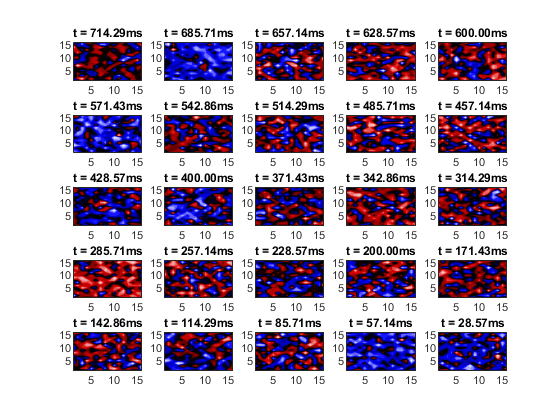

glm_sta = glm_weight(2:end);
glm_sta = reshape(glm_sta, [16,16,25]);
plot_sta(glm_sta, 25, 1/35);

#### Compute Log Likelihood of the Fitted Weights with the test data

logli = log_likli_poisson(test_var, test_lab, glm_weight, 1/35);
disp(logli);

  -2.0298e+04



exp(logli)

ans = 0